### **Breakdown of 9X21 Grid**

**Three vertical sections**: subject, verb, object

**Three horizontal sections**: prefix, affix, suffix

### Variables to keep at all points 

- Current X, Y, pressure and time ***Done***

- x and y position vectors (1-9 and 1-21) ***Done***

- pressure vector (1-3) ***Done***

- direction of movement (1-8) 

**Functions needed**

- Randomly choose origin in the prefix column 

-     Choose starting x(1-3)

-     Choose starting y(1-3)

- Randomly choose functions

- Randomly change direction

-     Directions allowed to move (N(1) to NW(8))    

- Randomly change pressure

- Randomly change speed 

**Move n= 1, 2, 3 or 4 units**      

### Subject (1,1 to 9,7)

% Hyperparameters
% k - scale of range of probabilities that forward direction can take
% n - skewness of distribution of direction probabilities
% origin_probabs - probability weights for choosing origin 
% propogation_probabs - probability weights for propogation 1 2 or 3 units at step
% 




% x0=[0.9 0.5 0.6 0.25 0.15 0.25 0.5 0.25 0.4 0.4 0.2];
% ratio = calculateGeneratorPerformance(x0);
% options = optimset('PlotFcns',@optimplotfval);
% x=fminsearch(@calculateGeneratorPerformance,x0,options)

% [gross_avg_data_density, gross_avg_ang_vel, gross_avg_dist_corner]=calculateGeneratorPerformance(0.9,0.5,0.6, 0.25, 0.15, 0.25, 0.5, 0.25, 0.4, 0.4, 0.2)

n=optimvar("n","LowerBound",0,"UpperBound",1);
k=optimvar("k","LowerBound",0,"UpperBound",1);
X_o=optimvar("X_o","LowerBound",1,"UpperBound",9,"Type","integer");

% Xop1=optimvar("Xop1","LowerBound",0.001,"UpperBound",1);
% Xop2=optimvar("Xop2","LowerBound",0.001,"UpperBound",1);
% Xop3=optimvar("Xop3","LowerBound",0.001,"UpperBound",1);
% Yop1=optimvar("Yop1","LowerBound",0.001,"UpperBound",1);
% Yop2=optimvar("Yop2","LowerBound",0.001,"UpperBound",1);
% Yop3=optimvar("Yop3","LowerBound",0.001,"UpperBound",1);
pp1=optimvar("pp1","LowerBound",0.001,"UpperBound",1);
pp2=optimvar("pp2","LowerBound",0.001,"UpperBound",1);
pp3=optimvar("pp3","LowerBound",0.001,"UpperBound",1);
[data_density, ang_vel, t_render]=fcn2optimexpr(@calculateGeneratorPerformance,n,k,X_o,pp1,pp2,pp3);
prob=optimproblem();
prob.Objective.data_density=data_density;
prob.Objective.ang_vel=ang_vel;
prob.Objective.t_render=t_render;
prob.ObjectiveSense.data_density="maximize";
prob.ObjectiveSense.ang_vel="minimize";
prob.ObjectiveSense.t_render="minimize";
% prob.Constraints.cons1=Xop1+Xop2+Xop3==1;
% prob.Constraints.cons2=Yop1+Yop2+Yop3==1;
prob.Constraints.cons1=pp1+pp2+pp3==1;
% prob.Constraints.cons4=Xop1*Xop2*Xop3>=0.03;
% prob.Constraints.cons5=Yop1*Yop2*Yop3>=0.03;
prob.Constraints.cons2=pp1*pp2*pp3>=0.03;
show(prob);
% init_sol=[0.2639 0.2376 0.4985 0.2807 0.2625 0.4567 0.1345 0.3291 0.2571 0.2313 0.5115,...
%           0.2638 0.2376 0.4985 0.2801 0.2628 0.4571 0.1344 0.3294 0.2568 0.2317 0.5055 ]
options = optimoptions('gamultiobj',...
    'PlotFcn',{@gaplotpareto},...
    'MaxGenerations',200,...
    'PopulationSize',50,...
    'Display','diagnose');
start = optimvalues(prob,...
    "X_o", [3 4 3 4 5 4 4 4 3 4 3],...
    "k", [0.1271 0.1264 0.1269 0.1261 0.1276 0.1266 0.1269 0.1293 0.1271 0.1266 0.1269],...
    "n",[0.3478 0.3520 0.3490 0.3542 0.3493 0.3511 0.3517 0.3432 0.3509 0.3514 0.3517],...
    "pp1", [0.2479 0.2480 0.2477 0.2470 0.2487 0.2474 0.2479 0.2508 0.2482 0.2481 0.2479],...
    "pp2",[0.2472 0.2469 0.2479 0.2500 0.2467 0.2485 0.2483 0.2427 0.2476 0.2468 0.2482],...
    "pp3",[0.5049 0.5051 0.5044 0.5030 0.5046 0.5041 0.5038 0.5065 0.5042 0.5051 0.5040]);
% X_o: [3 4 3 4 5 4 4 4 3 4 3]
%            k: [0.1271 0.1264 0.1269 0.1261 0.1276 0.1266 0.1269 0.1293 0.1271 0.1266 0.1269]
%            n: [0.3478 0.3520 0.3490 0.3542 0.3493 0.3511 0.3517 0.3432 0.3509 0.3514 0.3517]
%          pp1: [0.2479 0.2480 0.2477 0.2470 0.2487 0.2474 0.2479 0.2508 0.2482 0.2481 0.2479]
%          pp2: [0.2472 0.2469 0.2479 0.2500 0.2467 0.2485 0.2483 0.2427 0.2476 0.2468 0.2482]
%          pp3: [0.5049 0.5051 0.5044 0.5030 0.5046 0.5041 0.5038 0.5065 0.5042 0.5051 0.5040]
[sol,fval] = solve(prob,start,"Solver","gamultiobj","Options",options)


% sol = [0.2903 0.2644 0.4453 0.2331 0.2836 0.4833 0.1269 0.3264 0.2586 0.2327 0.5089]
X_o=4;
k=0.1271;
n=0.3466;
pp1=0.2477;
pp2=0.2450; 
pp3=.5072;
gestures = findBestGestures(n,k,X_o,pp1,pp2,pp3)

% switch_pressure_probabilities= [];
% switch_speed_probabilites=[];
% propagation_probabilities = [pp1 pp2 pp3];

gestures = 50×1 struct array with fields:
    X_positions
    Y_positions
    dir_sequence
    t_render
    angular_vel
    data_density


% 
% [X1_positions, Y1_positions, dir_sequence1, t_render1]=generateRandomGesture(X_o,propagation_probabilities, k, n, switch_pressure_probabilities, switch_speed_probabilites );
% plot(X1_positions,Y1_positions,'LineWidth',3)
% xlim([1 9])
% ylim([1 21])
% set(gca, 'YDir','reverse')
% grid on
% pbaspect([1 1 1])
% daspect([1 1 1])

for i=1:50
    for j=i:50
        score(i,j)=gestaltDistance(char(strjoin(string(gestures(i).dir_sequence))),char(strjoin(string(gestures(j).dir_sequence))));
    end
end

score = triu(score)+triu(score,1)';
sums= sum(score,2);
[sums,sortIdx] = sort(sums,'ascend');
sim_ranking_gestures=gestures(sortIdx);


gest_id=5;
plot_gesture(gestures(gest_id))

Unrecognized function or variable 'gestures'.

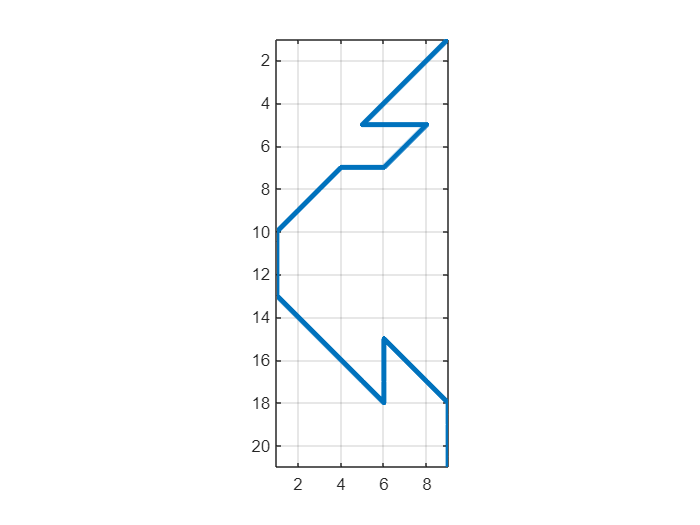

angular_vel = 39

t_render = 32

data_density = 0.6561


sim_gest_id =8;
plot_gesture(sim_ranking_gestures(sim_gest_id))




% for iter=1:10
%     plot_gesture(gestures(iter))
% end


% switch_pressure_probabilities= [];
% switch_speed_probabilites=[];
% propagation_probabilities = [pp1 pp2 pp3];
% [X1_positions, Y1_positions, dir_sequence1, t_render1]=generateRandomGesture(X_o,propagation_probabilities, k, n, switch_pressure_probabilities, switch_speed_probabilites );
% time_render1=t_render1
% data_density1=data_density_rel(X1_positions,Y1_positions)
% angular_vel1 = angular_vel_total(dir_sequence1)
% 
% [X2_positions, Y2_positions, dir_sequence2, t_render2]=generateRandomGesture(X_o,propagation_probabilities, k, n, switch_pressure_probabilities, switch_speed_probabilites );
% time_render2=t_render2
% data_density2=data_density_rel(X2_positions,Y2_positions)
% angular_vel2 = angular_vel_total(dir_sequence2)
% 
% gestalt_distance = gestaltDistance(char(strjoin(string(dir_sequence1))),char(strjoin(string(dir_sequence1))))
% frechet_distance = frechet(X1_positions',Y1_positions',X2_positions',Y2_positions')
% % distance1=dist_corner1
% % distance2=dist_corner2
% %Plot stroke
% plot(X1_positions,Y1_positions,'LineWidth',3)
% hold on 
% plot(X2_positions,Y2_positions,'LineWidth',3)
% xlim([1 9])
% ylim([1 21])
% set(gca, 'YDir','reverse')
% grid on
% pbaspect([1 1 1])
% daspect([1 1 1])
% hold off

% [gross_avg_data_density, gross_avg_ang_vel, gross_avg_t_render]=calculateGeneratorPerformance(n,k,X_o,pp1,pp2,pp3)



function f = findBestGestures(n,k,X_o,pp1,pp2,pp3)
propagation_probabilities = [pp1 pp2 pp3];
switch_pressure_probabilities = [];
switch_speed_probabilites = [];
gestures = [];
for iter = 1:50
    [X_positions, Y_positions, dir_sequence, t_render] = generateRandomGesture(X_o, propagation_probabilities, k, n, switch_pressure_probabilities, switch_speed_probabilites );
    gestures(iter).X_positions=X_positions;
    gestures(iter).Y_positions=Y_positions;
    gestures(iter).dir_sequence=dir_sequence;
    gestures(iter).t_render=t_render;
    gestures(iter).angular_vel=angular_vel_total(dir_sequence);
    gestures(iter).data_density=data_density_rel(X_positions,Y_positions);
end
gestures = table2struct(sortrows(struct2table(gestures),'t_render'));
f=gestures;
end

function plot_gesture(gesture)
hold off
plot(gesture.X_positions,gesture.Y_positions,'LineWidth',3)
xlim([1 9])
ylim([1 21])
set(gca, 'YDir','reverse')
grid on
pbaspect([1 1 1])
daspect([1 1 1])
angular_vel = gesture.angular_vel
t_render = gesture.t_render
data_density = gesture.data_density
end

function [gross_avg_data_density, gross_avg_ang_vel, gross_avg_t_render]=calculateGeneratorPerformance(n,k,X_o,pp1,pp2,pp3)
% X_origin_probabs = [Xop1 Xop2 Xop3];
% Y_origin_probabs = [Yop1 Yop2 Yop3];
propagation_probabilities = [pp1 pp2 pp3];
switch_pressure_probabilities = [];
switch_speed_probabilites = [];
generator_avg_ang_vel=[];
generator_avg_data_density=[];
generator_avg_t_render = [];
for iter=1:30
    [X_positions, Y_positions, dir_sequence, t_render] = generateRandomGesture(X_o, propagation_probabilities, k, n, switch_pressure_probabilities, switch_speed_probabilites );
    data_density=data_density_rel(X_positions,Y_positions);
    angular_vel = angular_vel_total(dir_sequence);
    generator_avg_ang_vel(end+1)=angular_vel;
    generator_avg_data_density(end+1)=data_density;
    generator_avg_t_render(end+1)=t_render;
%     scatter(data_density,average_angular_vel,50*ratio,"filled")
%     xlabel('data density')
%     ylabel('avg ang vel')
    hold on
end
    hold off
    gross_avg_data_density=sum(generator_avg_data_density)/20;
    gross_avg_ang_vel=sum(generator_avg_ang_vel)/20;
    gross_avg_t_render=sum(generator_avg_t_render)/20;
end



function [X_positions, Y_positions, dir_sequence, t_render]=generateRandomGesture(X_o, propagation_probabilities, k, n, switch_pressure_probabilities, switch_speed_probabilites )

s = RandStream('mlfg6331_64','Seed','shuffle');
X_positions = [];
Y_positions = [];
pressure_variation = [];
pressure_current = 0;
time_frame = 0;


load("gestemes.mat","gestemes");
% Choose origin
% Choose starting x and y
X_origin_probabs=randfixedsum(9,1,1,0,1);
[~,i]=max(X_origin_probabs);
X_origin_probabs=circshift(X_origin_probabs,floor(X_o)-i);
X_origin = randsample(s,1:9,1,true,X_origin_probabs);

% Y_origin = randsample(s,[1 2 3],1,true,Y_origin_probabs);
Y_origin = 1;
time_frame = 1;
X_positions(end+1)=X_origin;
Y_positions(end+1)=Y_origin;

pressure_current = 1;
pressure_variation(end+1)=pressure_current;
prop_dir = 0;
dir_sequence = [];
m=1; reached_edge=0; hitting_edge=0;
t_render=0;
% while m<=15 && reached_edge==0 && hitting_edge==0
while reached_edge==0 && hitting_edge==0
    m=m+1;
    % Randomly choose propogation length
    % Propogate 1-4 units
    last_dir = prop_dir;
    probab_gesture=0.3;
    probab_prop=1-probab_gesture;
    if length(X_positions)==1
        next_step=1;
    else
        next_step=randsample(s,[1 2],1,true,[probab_prop probab_gesture]);
    end
    if next_step==1
        dir = [1 2 3 4 5 6 7 8];
        Y = circshift(dir,-last_dir-3);
        opp_dir = Y(1);
        dir(dir==opp_dir)=[];
        prop_len = randsample(s,1:3,1,true,propagation_probabilities);
    
        % Calculate possible directions
        % -Cannot cross left edge
        if X_positions(end)-prop_len<=0
            dir(dir==6 | dir==7 | dir==8) = [];
        end
        % -Cannot cross top edge
        if Y_positions(end)-prop_len<=0
            dir(dir==8 | dir==1 | dir==2) = [];
        end
        % -Cannot cross right edge
        if X_positions(end)+prop_len>=10
            dir(dir==2 | dir==3 | dir==4) = [];
    % %         disp("hitting right edge, breaking")
    %            hitting_edge=1;
        end
        % -Cannot cross bottom edge
        if Y_positions(end)+prop_len>=22
            dir(dir==6 | dir==5 | dir==4) = [];
    %         disp("hitting right edge, breaking")
               hitting_edge=1;
        end
        
        % Select direction randomly
        dir_len = length(dir);
        sz = size(dir);
        dir_probabs = ones(sz)*(1/dir_len);
        prop_dir = randsample(s,dir,1,true,dir_probabs_gen(dir,k,n));
        
        iter = 1;
        % Propogate
        while iter<=prop_len && reached_edge==0
            iter = iter+1;
            time_frame = time_frame + 1;
            if prop_dir<5 && prop_dir>1
                X_positions(end+1)=X_positions(end)+1;
            end
            if prop_dir>5 && prop_dir<9
                X_positions(end+1)=X_positions(end)-1;
            end
            if prop_dir<7 && prop_dir>3
                Y_positions(end+1)=Y_positions(end)+1;
            end
            if prop_dir<3 || prop_dir>7
                Y_positions(end+1)=Y_positions(end)-1;
            end
            if prop_dir==1 || prop_dir==5
                X_positions(end+1)=X_positions(end);
            end
            if prop_dir==7 || prop_dir==3
                Y_positions(end+1)=Y_positions(end);
            end
            dir_sequence(end+1)=prop_dir;
            pressure_variation(end+1)=pressure_current;
    %         if X_positions(end)==9
            if Y_positions(end)==21
    %             disp("reached X=9 breaking")
                reached_edge=1;
            end 
        end
    end
    if next_step==2
        gesteme_pick_probabs = ones(length(gestemes),1)/length(gestemes);
        gesteme_id=randsample(s,1:length(gestemes),1,true,gesteme_pick_probabs);
%         gesteme_id=1;
        last_len=length(X_positions);
        gest_dir_seq=dir_seq_from_gesteme(gestemes,last_dir,gesteme_id);
        for i=1:length(gest_dir_seq)
            prop_dir=gest_dir_seq(i);
            if prop_dir<5 && prop_dir>1
                X_positions(end+1)=X_positions(end)+1;
            end
            if prop_dir>5 && prop_dir<9
                X_positions(end+1)=X_positions(end)-1;
            end
            if prop_dir<7 && prop_dir>3
                Y_positions(end+1)=Y_positions(end)+1;
            end
            if prop_dir<3 || prop_dir>7
                Y_positions(end+1)=Y_positions(end)-1;
            end
            if prop_dir==1 || prop_dir==5
                X_positions(end+1)=X_positions(end);
            end
            if prop_dir==7 || prop_dir==3
                Y_positions(end+1)=Y_positions(end);
            end
            pressure_variation(end+1)=pressure_current;
           
            dir_sequence(end+1)=prop_dir;
             if Y_positions(end)>21 || Y_positions(end)<1 || X_positions(end)>9 || X_positions(end)<1
    %            Revert Back
                indices= last_len:length(X_positions);
                X_positions(indices)=[];
                Y_positions(indices)=[];
                indices(end)=[];
                dir_sequence(indices)=[];
                pressure_variation(indices)=[];
                break;
            end 
        end
    end
    
%     dist_corner=norm([X_positions(end)-9 Y_positions(end)-7]);
        
end
t_render = length(X_positions);
end


% Randomly Choose dynamic variations                      Probabilities
% 0 : no change                                               0.7
% 1 : change pressure randomly 1 step up or down              0.2
% 2 : change speed 1 tempo randomly                           0.1


function y = data_density_rel(X_positions,Y_positions)
    gesture = zeros(21,9);
    for n=1:length(X_positions)
        gesture(Y_positions(n),X_positions(n))=1;
    end
    y = entropy(mat2gray(gesture)) ;
end

function y = dir_probabs_gen(dir,k,n)
% k=scale for range of probability for 3 between 2/7 and 1 (0-1)
% m=slope of distribution
m=rand*(1-n)+n;
min_probab_3 = (k*3 + 2)/7;
probab_3 = rand*(1-min_probab_3)+min_probab_3;
probabs=[];
m = m*min_probab_3/4;
% index= [1 2 3 4 5 6 7 8]
for i=1:length(dir)
    if dir(i)==5
        probabs(end+1)=probab_3;
    end
    if dir(i)==4 || dir(i)==6
        probabs(end+1)=probab_3-m;
    end
    if dir(i)==3 || dir(i)==7
        probabs(end+1)=probab_3-2*m;
    end
    if dir(i)==2 || dir(i)==8
        probabs(end+1)=probab_3-3*m;
    end
    if dir(i)==1
        probabs(end+1)=probab_3-4*m;
    end
end
y=probabs;
end

function y = gestaltDistance(X,Y)
total_len = (length(X) + length(Y))/2;
endloop = 0;
K=0;
while endloop==0
   [substr] = commonsubstring(char(X),char(Y));
   if isempty(substr)
       endloop=1;
   end
   if size(substr,1)>1
        for i=1:size(substr,1)
            K=K+length(substr(i,:));
            X=erase(X,substr(i,:));
            Y=erase(Y,substr(i,:));
        end
   else
       K=K+length(substr);
       X=erase(X,substr);
       Y=erase(Y,substr);
   end
end
y=(K)/total_len;
end


function y = angular_vel_total(X)
% Angular Velocity: rate of change of angle
% final angle - initial angle
% increase: (final - initial) * 45'
% decrease: abs(final - initial)* 45'
% ((b - a) + len) % len), where a is the "from" index, b is the "to" index, and len is the length of the array
    dirs = [1 2 3 4 5 6 7 8];
    av=0;
    for i=2:length(X)
        b=find(dirs==X(i));
        a=find(dirs==X(i-1));
        diff= mod(((b - a) + 8), 8);
        if diff<0
            disp("negative diff")
        end
        av=av+diff;
    end
    y=av;
end

function dir_seq=dir_seq_from_gesteme(gestemes,curr_dir,gest_ID)
insert_gesteme = str2mat(string(gestemes(gest_ID).seq));
insert_gesteme(insert_gesteme=='S'|insert_gesteme=='E')=[];
% insert_gesteme = '0022220';
app_dir_seq = [];
% app_dir_seq(end+1)=curr_dir;
for k=1:length(insert_gesteme)
    dirs = [1 2 3 4 5 6 7 8];
    dirs=circshift(dirs,-curr_dir+1);
    shift_by=str2num(insert_gesteme(k));
    shifted_dirs=circshift(dirs,shift_by);
    app_dir_seq(end+1)=shifted_dirs(1);
    curr_dir=shifted_dirs(1);
end
dir_seq=(app_dir_seq);
end
